# Cross-Temporal Decoding

fileDirs = [{'D:\WorkBigDataFiles\PFC\GE11_Session132'},...
    {'D:\WorkBigDataFiles\PFC\GE13_Session083'},...
    {'D:\WorkBigDataFiles\PFC\GE14_Session123'},...
    {'D:\WorkBigDataFiles\PFC\GE17_Session095'},...
    {'D:\WorkBigDataFiles\PFC\GE24_Session096'}];

binSize = 200;
dsRate = 1;
trlWindow = {[-800 2000]};
alignment = {'PokeIn'};
% trlWindow = {[-2000 700]};
% alignment = {'PokeOut'};
bayesType = 1; 
%bayseTypes: 1 = Poisson: use with raw spike counts; 2 = Bernoulli: use with binarized spike counts; 3 = Gaussian: Use with z-scored spike counts

numChancePerms = 10;

postCLim = [0 0.05];

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);
%#ok<*UNRCH> 


## Compile Data

tic;
for ani = 1:length(fileDirs)
    % Create & setup initial object and data variables (if initial file)
    mlb = MLB_SM(fileDirs{ani});
    % Create Analysis Variables
    if ani == 1 
        % Hold Durations
        trialHoldDurs = cell(length(mlb.odrVect), 1, length(fileDirs));
        % Real Posteriors
        trlHRs = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        trlFARs = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        trlDs = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        % Chance Posteriors
        chancePDF = cell(length(mlb.odrVect), 1);
        chanceOdr = cell(length(mlb.odrVect), 1);
    end
    mlb.binSize = binSize;
    mlb.dsRate = dsRate;
    mlb.windows = trlWindow;
    mlb.bayesType = 1;
    mlb.alignments = alignment;

    % Process Port Entry Aligned Observations
    mlb.SetLikes_ISC;
    mlb.Process_IterativeLikelyL1O;

    % First, to avoid nans and infinites any values that are ==1 or ==0 need to be replaced with the next nearest value
    allVals = unique([mlb.post{:}]);
    if min(allVals)==0
        minVal = allVals(2);
    else 
        minVal = allVals(1);
    end
    if max(allVals)==1
        maxVal = allVals(end-1);
    else
        maxVal = allVals(end);
    end
    clear allVals;
    for p1 = 1:mlb.seqLength
        for p2 = 1:mlb.seqLength
            temp_tempHRs = mlb.post(p1,1,:);
            temp_tempHRs(cellfun(@(a)isempty(a),temp_tempHRs)) = [];
            temp_temp_tempHRs = cell2mat(cellfun(@(a){a(:,:,p2)}, temp_tempHRs));
            temp_temp_tempHRs(temp_temp_tempHRs==0) = minVal;
            temp_temp_tempHRs(temp_temp_tempHRs==1) = maxVal;
            trlHRs{p1,p2,ani} = temp_temp_tempHRs;
%             faLog = (1:mlb.seqLength ~= p1) & (1:mlb.seqLength ~= p2);
            faLog = (1:mlb.seqLength ~= p1);
            temp_tempFARs = reshape(squeeze(mlb.post(faLog,1,:)), [1,1,numel(mlb.post)-(size(mlb.post,3)*sum(~faLog))]);
            temp_tempFARs(cellfun(@(a)isempty(a),temp_tempFARs)) = [];
            temp_temp_tempFARs = repmat(mean(cell2mat(cellfun(@(a){a(:,:,p2)},temp_tempFARs)),3,'omitnan'), [1,1,size(temp_tempHRs,3)]);
            temp_temp_tempFARs(temp_temp_tempFARs==0) = minVal;
            temp_temp_tempFARs(temp_temp_tempFARs==1) = maxVal;
            trlFARs{p1,p2,ani} = temp_temp_tempFARs;
        end
    end
    trlDs(:,:,ani) = cellfun(@(a,b){norminv(a)-norminv(b)}, trlHRs(:,:,ani), trlFARs(:,:,ani));
%     tempD = cellfun(@(a,b){(a)-(b)}, tempHRs, tempFARs);
    % Model fitting persistence test


    
    %%%%% Fill in rest of code code monkey!

    % Run persistence test
    % Calculate within vs across epoch decoding
    % Calculate pre-trial vs post-trial interval decoding for the trial period

end

Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed


toc

Elapsed time is 163.066442 seconds.


## Combine Trials Across Rats

groupHRs = cell(mlb.seqLength);
groupFARs = cell(mlb.seqLength);
groupDs = cell(mlb.seqLength);
for p1 = 1:mlb.seqLength
    for p2 = 1:mlb.seqLength
        groupHRs{p1,p2} = cell2mat(trlHRs(p1,p2,:));
        groupFARs{p1,p2} = cell2mat(trlFARs(p1,p2,:));
        groupDs{p1,p2} = cell2mat(trlDs(p1,p2,:));
    end
end


## Quick Dirty Plots

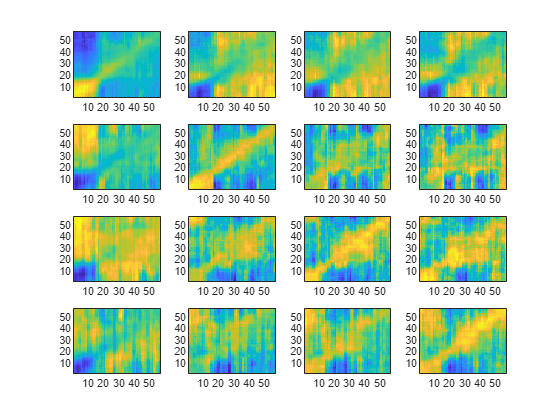

% for z = 1:numel(groupHRs); subplot(4,4,z); imagesc(mean(groupHRs{z},3));end
% figure; 
% for z = 1:numel(groupHRs); subplot(4,4,z); imagesc(mean(groupFARs{z},3));end
figure; 
for z = 1:numel(groupHRs)
    subplot(4,4,z); 
    imagesc(mean(groupDs{z},3));
    set(gca, 'ydir', 'normal');
end

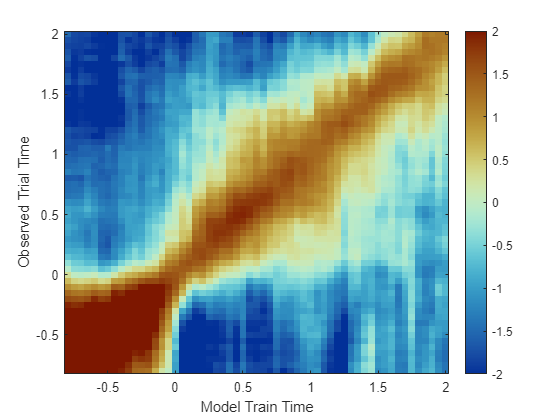

iscs = cell2mat(reshape(groupDs(logical(eye(mlb.seqLength))), [1,1,mlb.seqLength]));
figure;
imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,mean(iscs,3),[-2 2]);
set(gca,'ydir', 'normal');
colormap(cMap);
xlabel('Model Train Time');
ylabel('Observed Trial Time');
colorbar